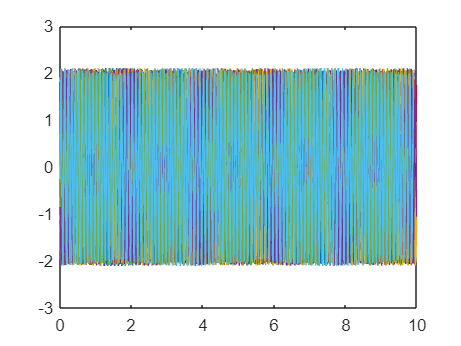

% time_x = {ent_sen_2_1_Time, ent_sen_2_2_Time, ent_sen_2_3_Time, ent_sen_2_4_Time, ent_sen_2_5_Time, ent_sen_2_6_Time, ent_sen_2_7_Time, ent_sen_2_8_Time, ent_sen_2_9_Time, ent_sen_2_10_Time};
% time_y = {sai_sen_2_1_Time(:,1), sai_sen_2_2_Time(:,1), sai_sen_2_3_Time(:,1), sai_sen_2_4_Time(:,1), sai_sen_2_5_Time(:,1), sai_sen_2_6_Time(:,1), sai_sen_2_7_Time(:,1), sai_sen_2_8_Time(:,1), sai_sen_2_9_Time(:,1), sai_sen_2_10_Time(:,1)};
% 
% x = {ent_sen_2_1_Value, ent_sen_2_2_Value, ent_sen_2_3_Value, ent_sen_2_4_Value, ent_sen_2_5_Value, ent_sen_2_6_Value, ent_sen_2_7_Value, ent_sen_2_8_Value, ent_sen_2_9_Value, ent_sen_2_10_Value};
% y = {sai_sen_2_1_Value(:,1), sai_sen_2_2_Value(:,1), sai_sen_2_3_Value(:,1), sai_sen_2_4_Value(:,1), sai_sen_2_5_Value(:,1), sai_sen_2_6_Value(:,1), sai_sen_2_7_Value(:,1), sai_sen_2_8_Value(:,1), sai_sen_2_9_Value(:,1), sai_sen_2_10_Value(:,1)};

time_x = {senf020a200Ent_Time, senf060a200Ent_Time, senf500a200Ent_Time, senf550a200Ent_Time, senf600a200Ent_Time, senf650a200Ent_Time, senf700a200Ent_Time, senf750a200Ent_Time, senf800a200Ent_Time, senf850a200Ent_Time, senf900a200Ent_Time, senf950a200Ent_Time, senf1000a200Ent_Time};
time_y = {senf020a200Sai_Time(:,1), senf060a200Sai_Time(:,1), senf500a200Sai_Time(:,1), senf550a200Sai_Time(:,1), senf600a200Sai_Time(:,1), senf650a200Sai_Time(:,1), senf700a200Sai_Time(:,1), senf750a200Sai_Time(:,1), senf800a200Sai_Time(:,1), senf850a200Sai_Time(:,1), senf900a200Sai_Time(:,1), senf950a200Sai_Time(:,1), senf1000a200Sai_Time(:,1)};

x = {senf020a200Ent_Value, senf060a200Ent_Value, senf500a200Ent_Value, senf550a200Ent_Value, senf600a200Ent_Value, senf650a200Ent_Value, senf700a200Ent_Value, senf750a200Ent_Value, senf800a200Ent_Value, senf850a200Ent_Value, senf900a200Ent_Value, senf950a200Ent_Value, senf1000a200Ent_Value};
y = {senf020a200Sai_Value(:,1), senf060a200Sai_Value(:,1), senf500a200Sai_Value(:,1), senf550a200Sai_Value(:,1), senf600a200Sai_Value(:,1), senf650a200Sai_Value(:,1), senf700a200Sai_Value(:,1), senf750a200Sai_Value(:,1), senf800a200Sai_Value(:,1), senf850a200Sai_Value(:,1), senf900a200Sai_Value(:,1), senf950a200Sai_Value(:,1), senf1000a200Sai_Value(:,1)};


graf_init = 1;
graf_end = 13;

%201 -> 351
for i = graf_init:graf_end
    time_x{i}= time_x{i}-time_x{i}(1);
    plot(time_x{i},x{i})
    hold on
end
hold off

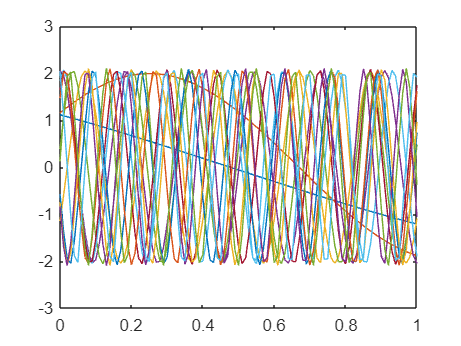

range_time_x = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_x = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_x(j+1, i)= time_x{i}(length(time_x{i})-100+j)-time_x{i}(length(time_x{i})-100);
        range_x(j+1, i)= x{i}(length(time_x{i})-100+j);
    end
end

range_time_y = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_y = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_y(j+1, i)= time_y{i}(length(time_y{i})-100+j)-time_y{i}(length(time_y{i})-100);
        range_y(j+1, i)= y{i}(length(time_y{i})-100+j);
    end
end

plot(range_time_x(:,:),range_x(:,:))

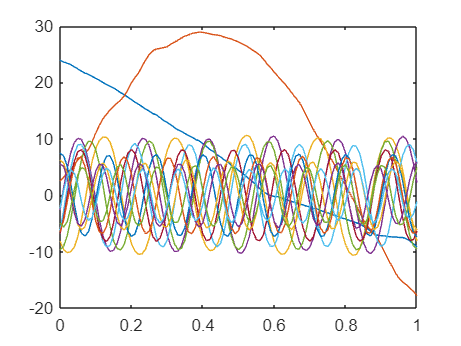

plot(range_time_y(:,:),range_y(:,:))

x_mx_fft = fft(range_x);
y_mx_fft = fft(range_y);

[x_max, x_ind] = max(abs(x_mx_fft));
[y_max, y_ind] = max(abs(y_mx_fft));

x_angle_max = angle(x_mx_fft(x_ind));
y_angle_max = angle(y_mx_fft(y_ind));

phaseResponse2 = y_angle_max - x_angle_max

phaseResponse2 =     0.1289    1.5337    0.0165    0.0508    0.0508   -0.0367   -0.0367   -0.0096   -0.0096   -0.0911   -0.0911   -0.0306   -0.0306



magnitudeResponse2 = y_max./x_max

magnitudeResponse2 =    15.1165   15.9035    5.3747    4.7972    4.9349    4.4998    4.1222    3.8750    3.4565    3.1598    2.8752    2.7689    2.3659


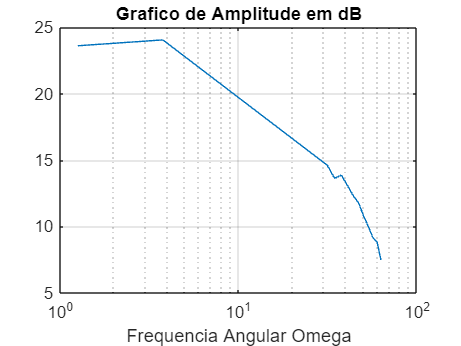

%pegando as frequências medidas
%frequencySample

%frequencies = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
frequencies = [0.2, 0.6, 5, 5.5, 6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5, 10];


omega2 = zeros(1, graf_end-graf_init+1);
ampl2 = zeros(1, graf_end-graf_init+1);


for i = graf_init:graf_end
    omega2(i) = 2*pi*frequencies(1,i);
    ampl2(i) = 20*log10(magnitudeResponse2(1,i));
end

semilogx(omega2,ampl2,'-')
title('Grafico de Amplitude em dB');
xlabel ('Frequencia Angular Omega') ;

grid on

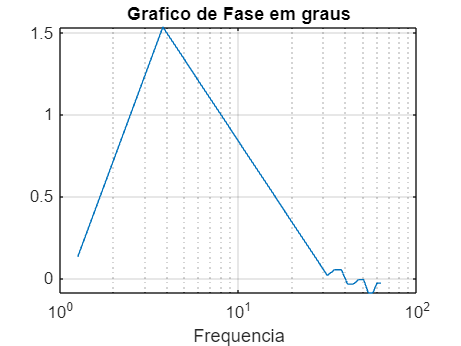


fase2 = zeros(1, graf_end-graf_init+1);

for i = graf_init:graf_end
    fase2(i) = phaseResponse2(i);
end

semilogx(omega2, fase2)
title ('Grafico de Fase em graus');
xlabel ('Frequencia');

grid on

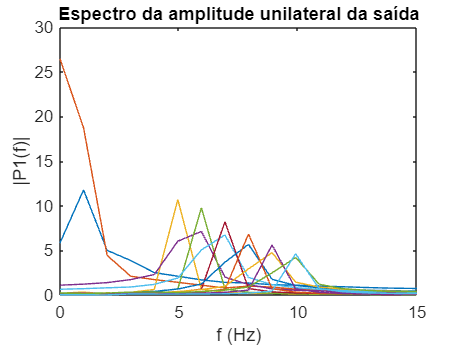

N = length(y_mx_fft(:,1));
frequencySample = 1/0.01;
frequenciesSample = frequencySample*(0:(N/2))/N;


P2 = abs(y_mx_fft/N);
P1 = P2(1:floor(N/2)+1,:);
P1(2:end-1) = 2*P1(2:end-1);

for i = graf_init:graf_end
    plot(frequenciesSample,P1(:,i))
    hold on
end
hold off

title("Espectro da amplitude unilateral da saída")
xlabel("f (Hz)")
ylabel("|P1(f)|")
xlim([0 15])


% for i = graf_init:graf_end
%     plot(2* pi*range_time_y(1:50), abs(fft_range_y(1:50,i)))
%     hold on
% end
% hold off
% 
% title("Single-Sided Amplitude Spectrum of output(t)")
% xlabel("f (Hz)")
% ylabel("|P1(f)|")

x_fft = cell(1,graf_end-graf_init+1);
y_fft = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    x_fft{i} = fft(x{i});
    y_fft{i} = fft(y{i});
end

H = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    H{i} = y_fft{i}./x_fft{i};
end

%pegando as frequências medidas
%frequencySample
frequencies = [0.2, 0.6, 2, 5, 5.5, 6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5, 10];

magnitudeResponse = zeros(1,graf_end-graf_init+1)

magnitudeResponse =      0     0     0     0     0     0     0     0     0     0     0     0     0


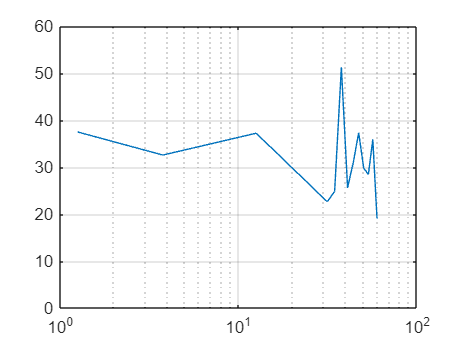

phaseResponse = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    [magnitudeResponse(i),  index]= max(abs(H{i}));
    phaseResponse{i} = rad2deg(angle(H{i}(index)));
end
figure;

omega = zeros(graf_end-graf_init+1);
ampl = zeros(graf_end-graf_init+1);

for i = graf_init:graf_end
    omega(i) = 2*pi*frequencies(i);
    ampl(i) = 20*log10(magnitudeResponse(i));
end

semilogx(omega,ampl,'-')
grid on

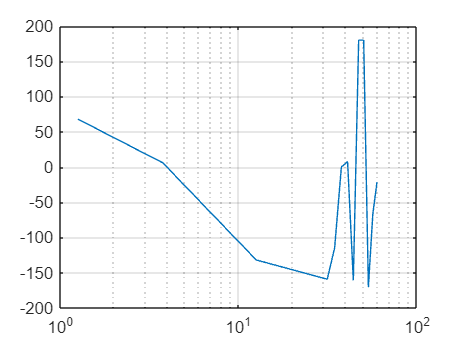


fase = zeros(graf_end-graf_init+1);

for i = graf_init:graf_end
    fase(i) = phaseResponse{i};
end

semilogx(omega, fase)
grid on